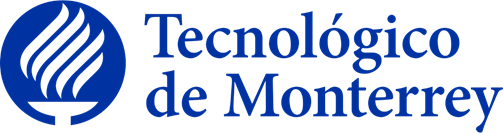

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

TE3002B.502 

**Implementación de robótica Inteligente (Gpo 502)**

Semestre: febrero - junio 2023   

**Actividad:**

Actividad 6 (SLAM de LiDAR)  

**Alumno:**

		José Angel Ramírez Ramírez   	A01735529

**Profesor: Dr. Alfredo Garcia Suarez.**

Fecha de entrega: 06 de Mayo del 2023

1.** Implementar** el código requerido para generar el seguimiento de los siguientes waypoints de forma aleatoria, ajustando los parámetros: **sampleTime****,** **tVec****,** **initPose****,** **lidar.scanAngles****,** **lidar.maxRange****,** **waypoints****,** **controller****.LookaheadDistance****,** **controller.****DesiredLinearVelocity** **y** **controller.****MaxAngularVelocity****.** Evadiendo los obstáculos del mapa de navegación “exampleMap”

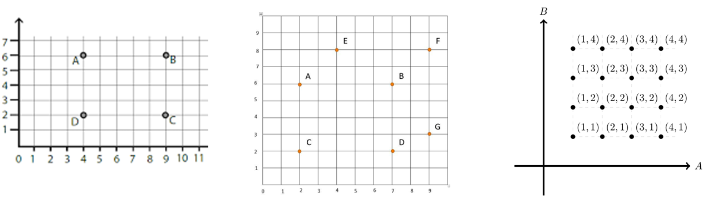

Llevar a cabo la actividad, se utilizo como base el siguiente ejemplo de codigo

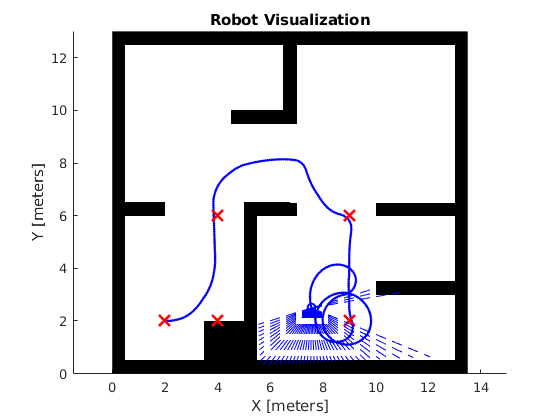

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:45;        % Time array

% Initial conditions
initPose = [2;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

% Load map
close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,51);
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 10;
             11 8;
             8 2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.75;
controller.MaxAngularVelocity = 1.5;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3];
vfh.NumAngularSectors = 36;
vfh.HistogramThresholds = [5 10];
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.25;

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

del cual solo se modificaron los mencionados en las indicaciones.

Trayectoria 1: Debido a que en la primera coordenada el robot colisionaba con el robot, y que en la segunda no podia pasar por la zona segura que debe mantener el robot, se modificaron las cordenadas en el eje x, donde solo se resto una unidad. 


% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:20.2;        % Time array

% Initial conditions
initPose = [3;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

% Load map
close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,51);
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             3 6;
             8 6;
             8 2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.75;
controller.MaxAngularVelocity = 1.5;

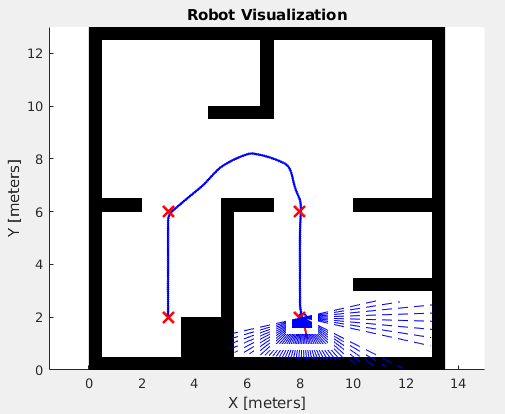

Trayectoria 2: Para esta trayectoria no se modificaron las coordenadas como se hizo en el punto anterior, por lo cual como algunos puntos quedaron justo a un lado de las paredes, el robot no pudo pasar por esos puntos. 

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:27;        % Time array

% Initial conditions
initPose = [2;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

% Load map
close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,51);
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 6;
             4 8;
             9 8;
             7 6;
             9 3;
             7 2];

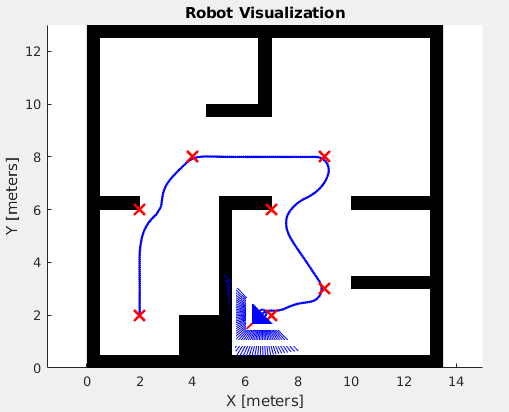

Trayectoria 3: Principalmente para este ejercicio se modifico el rango maximo del LIDAR, ya que los puntos estaban muy cercanos a las paredes, tener un alcance muy alto impactaba que el robot se alejara mucho de los puntos y que no pasara por ellos

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:17;        % Time array

% Initial conditions
initPose = [1;1;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

% Load map
close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,51);
lidar.maxRange = 0.4;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             1 2;
             1 3;
             1 4;
             2 4;
             2 3;
             2 2;
             2 1;
             3 1;
             3 2;
             3 3;
             3 4;
             4 4;
             4 3;
             4 2;
             4 1];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.75;
controller.MaxAngularVelocity = 1.5;

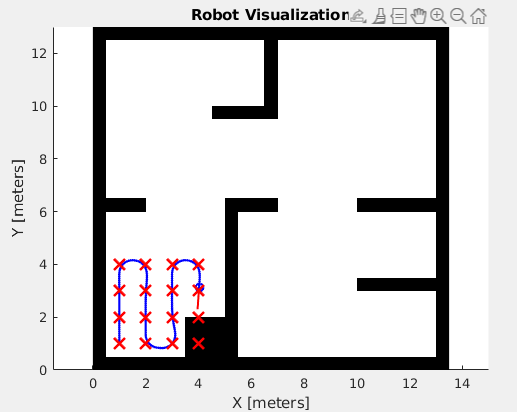

2.** Implementar** el código requerido para generar el seguimiento de los siguientes waypoints de forma secuencial: **(1, 2), (2, 10), (11, 8), (8, 2), (8, 8) y (1, 2)** ajustando los parámetros: **sampleTime****,** **tVec****,** **initPose****,** **scanAngles****,** **lidar.maxRange****,** **waypoints,controller.LookaheadDistance****,** **controller.DesiredLinearVelocity** **y** **controller.MaxAngularVelocity****.** Evadiendo los obstáculos del mapa de navegación “exampleMap”

En este ejercicio la una complicacion fue que como el punto final, que es el mismo que el inicial, esta muy cerca de la pared, al querer regresar tuvo que dar una vuelta antes de poder llegar, ya que como el rango de alcance del LIDAR era de 5mts este trataba de evitar la pared, una posible solucion pudo haber bajado dicho rango, pero esto treria mas complicaciones al llegar a los demas puntos. 


% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:71;        % Time array

% Initial conditions
initPose = [1;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

% Load map
close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,51);
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 10;
             11 8;
             8 2;
             8 8;
             1 2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.75;
controller.MaxAngularVelocity = 1.5;